%%
load('grant_graph.mat')

Error using load
Unable to read file 'grant_graph.mat'. No such file or directory.

close all

## Endpoint Distribution

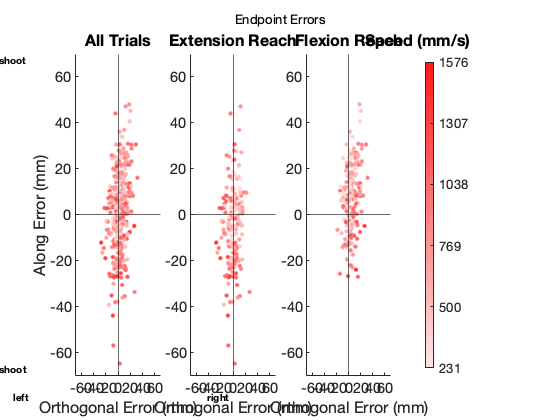

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
alphaRange = [0.1,0.9];
theme_color = [1 0 0];
map = theme_color .* linspace(alphaRange(1),alphaRange(2),100)' + [1 1 1] .* (1-linspace(alphaRange(1),alphaRange(2),100)');


figure(1)
subplot(1,4,1)
alphaRange = [0.1,0.9];
speed2alpha = (maxSpeed-min(maxSpeed)) ./ (max(maxSpeed)-min(maxSpeed)) .* (alphaRange(2)-alphaRange(1)) + alphaRange(1);
d = scatter(copy(:,29),copy(:,23),'.','SizeData',150);
d.MarkerFaceColor = 'flat';
d.CData = theme_color .* speed2alpha + [1 1 1] .* (1-speed2alpha);
% d.AlphaData = speed2alpha;
% d.SizeDataMode = 'manual';
% d.SizeData = 10;
ylims = [-70,70];
xticks(-60:20:60)
yticks(-60:20:60)
xlim(ylims)
ylim(ylims)

xlabel('Orthogonal Error (mm)')
ylabel('Along Error (mm)')
title('All Trials')
xline(0)
yline(0)
nw_label = 'Overshoot                                 ';
sw_label = 'Undershoot                                 ';
text(0.05, max(ylims), nw_label, 'FontWeight', 'bold', 'HorizontalAlignment','right','VerticalAlignment', 'top');
text(0.05, min(ylims), sw_label, 'FontWeight', 'bold', 'HorizontalAlignment','right','VerticalAlignment', 'bottom');
nw_label = 'left                                ';
sw_label = '                                right';
text(0.05, min(ylims)-12, nw_label, 'FontWeight', 'bold', 'HorizontalAlignment','right','VerticalAlignment', 'bottom');
text(0.05, min(ylims)-12, sw_label, 'FontWeight', 'bold', 'HorizontalAlignment','left','VerticalAlignment', 'bottom');



subplot(1,4,2)
alphaRange = [0.1,0.9];
speed2alpha = (rightward-min(rightward)) ./ (max(maxSpeed)-min(maxSpeed)) .* (alphaRange(2)-alphaRange(1)) + alphaRange(1);
d = scatter(yRight,xRight,'.','SizeData',150);
d.MarkerFaceColor = 'flat';
d.CData = theme_color .* speed2alpha + [1 1 1] .* (1-speed2alpha);
xlim([-70,70])
ylim([-70,70])
xlabel('Orthogonal Error (mm)')
title('Extension Reach')
xticks(-60:20:60)
yticks(-60:20:60)
xline(0)
yline(0)

subplot(1,4,3)
alphaRange = [0.1,0.9];
speed2alpha = (leftward-min(leftward)) ./ (max(maxSpeed)-min(maxSpeed)) .* (alphaRange(2)-alphaRange(1)) + alphaRange(1);
d = scatter(yLeft,xLeft,'.','SizeData',150);
d.MarkerFaceColor = 'flat';
d.CData = theme_color .* speed2alpha + [1 1 1] .* (1-speed2alpha);xlim([-40,40])
ylim([-70,70])
xlim([-70,70])
xlabel('Orthogonal Error (mm)')
title('Flexion Reach')
xticks(-60:20:60)
yticks(-60:20:60)
xline(0)
yline(0)

subplot(1,4,4)
colormap(map)
cbtValues = round(linspace(min(maxSpeed),max(maxSpeed),6));
cBarTickLabels = {num2str(cbtValues(1)),num2str(cbtValues(2)),num2str(cbtValues(3)),...
    num2str(cbtValues(4)),num2str(cbtValues(5)),num2str(cbtValues(6))};
colorbar('Ticks',0:0.2:1,'TickLabels',cBarTickLabels,'Location','west');
title('Speed (mm/s)                     ','FontWeight','bold');
axis off
sgtitle('Endpoint Errors')

close all

## Along Error Fit

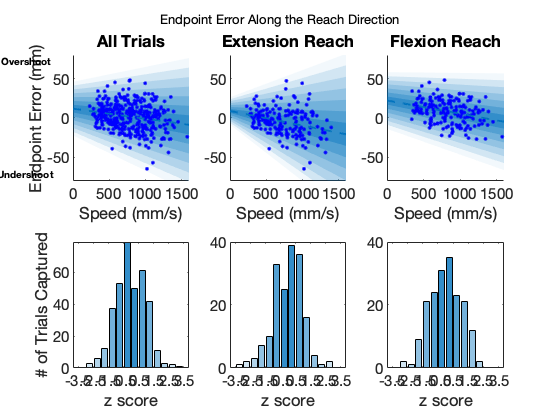

figure(2)
indices = 1:1600;
subplot(2,3,1)
theme_color = [0 0.4470 0.7410];
central_linfit = (xParams(1,1) .* indices) + xParams(1,2);
predict_bias = (xParams(1,1) .* maxSpeed) + xParams(1,2);
predict_std = (xParams(1,3) * maxSpeed) + xParams(1,4);
z_scores = (xTotal-predict_bias)./predict_std;
ylims = [-80,80];
shades_n = 7;
z_gr = linspace(0,3.5,shades_n+1);
shade_gr = linspace(0.8,0.05,shades_n);
trials_bin = NaN(1,shades_n *2);
hold on
for i = 1:shades_n
    x_UUB = central_linfit + z_gr(i+1) .* (xParams(1,3) * indices + xParams(1,4));
    x_ULB = central_linfit + z_gr(i) .* (xParams(1,3) * indices + xParams(1,4));
    x_LUB = central_linfit - z_gr(i) .* (xParams(1,3) * indices + xParams(1,4));
    x_LLB = central_linfit - z_gr(i+1) .* (xParams(1,3) * indices + xParams(1,4));
    patch([indices,fliplr(indices)],[x_UUB,fliplr(x_ULB)], theme_color, 'FaceAlpha', shade_gr(i), 'EdgeColor','none')
    patch([indices,fliplr(indices)],[x_LUB,fliplr(x_LLB)], theme_color, 'FaceAlpha', shade_gr(i), 'EdgeColor','none')
    trials_bin(shades_n-i+1) = sum(z_scores(:) > z_gr(i) & z_scores(:) < z_gr(i+1));
    trials_bin(shades_n+i) = sum(z_scores(:) < -z_gr(i) & z_scores(:) > -z_gr(i+1));
end

plot(maxSpeed,xTotal,'.b','MarkerSize',10)
plot(indices,central_linfit,'--','Color',theme_color,'LineWidth',2)

hold off

xlabel('Speed (mm/s)')
ylabel('Endpoint Error (mm)')
title('All Trials')
xlim([0,1600])
ylim(ylims)
xticks(0:500:1500)

% Add labels to the northwest and southwest corners of the plot
nw_label = 'Overshoot        ';
sw_label = 'Undershoot       ';
text(0.05, max(ylims), nw_label, 'FontWeight', 'bold', 'HorizontalAlignment','right','VerticalAlignment', 'top');
text(0.05, min(ylims), sw_label, 'FontWeight', 'bold', 'HorizontalAlignment','right','VerticalAlignment', 'bottom');

subplot(2,3,4)
b = bar(trials_bin);
b.FaceColor = 'flat';
tColor = repmat(theme_color,shades_n * 2,1);
bColor = repmat([1 1 1],shades_n * 2,1);
b.CData = tColor.*[fliplr(shade_gr),shade_gr]' + (1-[fliplr(shade_gr),shade_gr]').*bColor;
ylabel('# of Trials Captured')
xlabel('z score')
bin_ticks = 0.5:2:shades_n *2+0.5;
bin_ticklabels = [-fliplr(z_gr(2:2:end)),z_gr(2:2:end)];
xticks(bin_ticks)
xticklabels(bin_ticklabels)



subplot(2,3,2)
theme_color = [0 0.4470 0.7410];
central_linfit = (xParams(2,1) .* indices) + xParams(2,2);
predict_bias = (xParams(2,1) .* rightward) + xParams(2,2);
predict_std = (xParams(2,3) * rightward) + xParams(2,4);
z_scores = (xRight-predict_bias)./predict_std;
hold on
shades_n = 7;
z_gr = linspace(0,3.5,shades_n+1);
shade_gr = linspace(0.8,0.05,shades_n);
trials_bin = NaN(1,shades_n *2);
for i = 1:shades_n
    x_UUB = central_linfit + z_gr(i+1) .* (xParams(2,3) * indices + xParams(2,4));
    x_ULB = central_linfit + z_gr(i) .* (xParams(2,3) * indices + xParams(2,4));
    x_LUB = central_linfit - z_gr(i) .* (xParams(2,3) * indices + xParams(2,4));
    x_LLB = central_linfit - z_gr(i+1) .* (xParams(2,3) * indices + xParams(2,4));
    patch([indices,fliplr(indices)],[x_UUB,fliplr(x_ULB)], theme_color, 'FaceAlpha', shade_gr(i), 'EdgeColor','none')
    patch([indices,fliplr(indices)],[x_LUB,fliplr(x_LLB)], theme_color, 'FaceAlpha', shade_gr(i), 'EdgeColor','none')
    trials_bin(shades_n-i+1) = sum(z_scores(:) > z_gr(i) & z_scores(:) < z_gr(i+1));
    trials_bin(shades_n+i) = sum(z_scores(:) < -z_gr(i) & z_scores(:) > -z_gr(i+1));
end



plot(rightward,xRight,'.b','MarkerSize',10)
plot(indices,central_linfit,'--','Color',theme_color,'LineWidth',2)

hold off

xlabel('Speed (mm/s)')
title('Extension Reach')
xlim([0,1600])
ylim(ylims)
xticks(0:500:1500)

subplot(2,3,5)
b = bar(trials_bin);
b.FaceColor = 'flat';
tColor = repmat(theme_color,shades_n * 2,1);
bColor = repmat([1 1 1],shades_n * 2,1);
b.CData = tColor.*[fliplr(shade_gr),shade_gr]' + (1-[fliplr(shade_gr),shade_gr]').*bColor;
xlabel('z score')
bin_ticks = 0.5:2:shades_n *2+0.5;
bin_ticklabels = [-fliplr(z_gr(2:2:end)),z_gr(2:2:end)];
xticks(bin_ticks)
xticklabels(bin_ticklabels)


subplot(2,3,3)
theme_color = [0 0.4470 0.7410];
central_linfit = (xParams(3,1) .* indices) + xParams(3,2);
predict_bias = (xParams(3,1) .* leftward) + xParams(3,2);
predict_std = (xParams(3,3) * leftward) + xParams(3,4);
z_scores = (xLeft-predict_bias)./predict_std;
hold on
shades_n = 7;
z_gr = linspace(0,3.5,shades_n+1);
shade_gr = linspace(0.8,0.05,shades_n);
trials_bin = NaN(1,shades_n *2);
for i = 1:shades_n
    x_UUB = central_linfit + z_gr(i+1) .* (xParams(3,3) * indices + xParams(3,4));
    x_ULB = central_linfit + z_gr(i) .* (xParams(3,3) * indices + xParams(3,4));
    x_LUB = central_linfit - z_gr(i) .* (xParams(3,3) * indices + xParams(3,4));
    x_LLB = central_linfit - z_gr(i+1) .* (xParams(3,3) * indices + xParams(3,4));
    patch([indices,fliplr(indices)],[x_UUB,fliplr(x_ULB)], theme_color, 'FaceAlpha', shade_gr(i), 'EdgeColor','none')
    patch([indices,fliplr(indices)],[x_LUB,fliplr(x_LLB)], theme_color, 'FaceAlpha', shade_gr(i), 'EdgeColor','none')
    trials_bin(shades_n-i+1) = sum(z_scores(:) > z_gr(i) & z_scores(:) < z_gr(i+1));
    trials_bin(shades_n+i) = sum(z_scores(:) < -z_gr(i) & z_scores(:) > -z_gr(i+1));
end



plot(leftward,xLeft,'.b','MarkerSize',10)
plot(indices,central_linfit,'--','Color',theme_color,'LineWidth',2)

hold off

xlabel('Speed (mm/s)')
title('Flexion Reach')
xlim([0,1600])
ylim(ylims)
xticks(0:500:1500)

subplot(2,3,6)
b = bar(trials_bin);
b.FaceColor = 'flat';
tColor = repmat(theme_color,shades_n * 2,1);
bColor = repmat([1 1 1],shades_n * 2,1);
b.CData = tColor.*[fliplr(shade_gr),shade_gr]' + (1-[fliplr(shade_gr),shade_gr]').*bColor;
xlabel('z score')
bin_ticks = 0.5:2:shades_n *2+0.5;
bin_ticklabels = [-fliplr(z_gr(2:2:end)),z_gr(2:2:end)];
xticks(bin_ticks)
xticklabels(bin_ticklabels)


sgtitle('Endpoint Error Along the Reach Direction')

## Orthogonal Error Fit

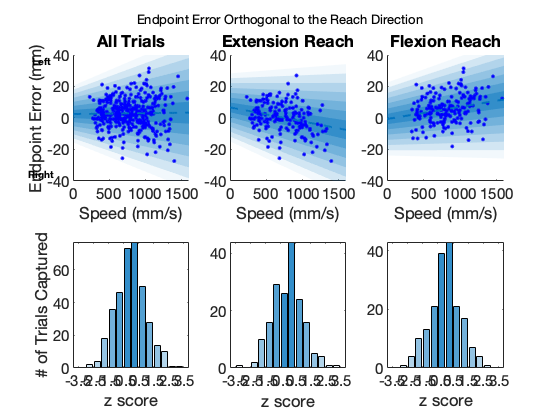

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(3)
indices = 1:1600;
subplot(2,3,1)
theme_color = [0 0.4470 0.7410];
central_linfit = (yParams(1,1) .* indices) + yParams(1,2);
predict_bias = (yParams(1,1) .* maxSpeed) + yParams(1,2);
predict_std = (yParams(1,3) * maxSpeed) + yParams(1,4);
z_scores = (yTotal-predict_bias)./predict_std;
ylims = [-40,40];
shades_n = 7;
z_gr = linspace(0,3.5,shades_n+1);
shade_gr = linspace(0.8,0.05,shades_n);
trials_bin = NaN(1,shades_n *2);
hold on

for i = 1:shades_n
    y_UUB = central_linfit + z_gr(i+1) .* (yParams(1,3) * indices + yParams(1,4));
    y_ULB = central_linfit + z_gr(i) .* (yParams(1,3) * indices + yParams(1,4));
    y_LUB = central_linfit - z_gr(i) .* (yParams(1,3) * indices + yParams(1,4));
    y_LLB = central_linfit - z_gr(i+1) .* (yParams(1,3) * indices + yParams(1,4));
    patch([indices,fliplr(indices)],[y_UUB,fliplr(y_ULB)], theme_color, 'FaceAlpha', shade_gr(i), 'EdgeColor','none')
    patch([indices,fliplr(indices)],[y_LUB,fliplr(y_LLB)], theme_color, 'FaceAlpha', shade_gr(i), 'EdgeColor','none')
    trials_bin(shades_n-i+1) = sum(z_scores(:) > z_gr(i) & z_scores(:) < z_gr(i+1));
    trials_bin(shades_n+i) = sum(z_scores(:) < -z_gr(i) & z_scores(:) > -z_gr(i+1));
end



plot(maxSpeed,yTotal,'.b','MarkerSize',10)
plot(indices,central_linfit,'--','Color',theme_color,'LineWidth',2)

hold off

xlabel('Speed (mm/s)')
ylabel('Endpoint Error (mm)')
title('All Trials')
xlim([0,1600])
ylim(ylims)
xticks(0:500:1500)

% Add labels to the northwest and southwest corners of the plot
nw_label = 'Left        ';
sw_label = 'Right       ';
text(0.05, max(ylims), nw_label, 'FontWeight', 'bold', 'HorizontalAlignment','right','VerticalAlignment', 'top');
text(0.05, min(ylims), sw_label, 'FontWeight', 'bold', 'HorizontalAlignment','right','VerticalAlignment', 'bottom');

subplot(2,3,4)
b = bar(trials_bin);
b.FaceColor = 'flat';
tColor = repmat(theme_color,shades_n * 2,1);
bColor = repmat([1 1 1],shades_n * 2,1);
b.CData = tColor.*[fliplr(shade_gr),shade_gr]' + (1-[fliplr(shade_gr),shade_gr]').*bColor;
ylabel('# of Trials Captured')
xlabel('z score')
bin_ticks = 0.5:2:shades_n *2+0.5;
bin_ticklabels = [-fliplr(z_gr(2:2:end)),z_gr(2:2:end)];
xticks(bin_ticks)
xticklabels(bin_ticklabels)



subplot(2,3,2)
theme_color = [0 0.4470 0.7410];
central_linfit = (yParams(2,1) .* indices) + yParams(2,2);
predict_bias = (yParams(2,1) .* rightward) + yParams(2,2);
predict_std = (yParams(2,3) * rightward) + yParams(2,4);
z_scores = (yRight-predict_bias)./predict_std;
hold on
shades_n = 7;
z_gr = linspace(0,3.5,shades_n+1);
shade_gr = linspace(0.8,0.05,shades_n);
trials_bin = NaN(1,shades_n *2);
for i = 1:shades_n
    y_UUB = central_linfit + z_gr(i+1) .* (yParams(2,3) * indices + yParams(2,4));
    y_ULB = central_linfit + z_gr(i) .* (yParams(2,3) * indices + yParams(2,4));
    y_LUB = central_linfit - z_gr(i) .* (yParams(2,3) * indices + yParams(2,4));
    y_LLB = central_linfit - z_gr(i+1) .* (yParams(2,3) * indices + yParams(2,4));
    patch([indices,fliplr(indices)],[y_UUB,fliplr(y_ULB)], theme_color, 'FaceAlpha', shade_gr(i), 'EdgeColor','none')
    patch([indices,fliplr(indices)],[y_LUB,fliplr(y_LLB)], theme_color, 'FaceAlpha', shade_gr(i), 'EdgeColor','none')
    trials_bin(shades_n-i+1) = sum(z_scores(:) > z_gr(i) & z_scores(:) < z_gr(i+1));
    trials_bin(shades_n+i) = sum(z_scores(:) < -z_gr(i) & z_scores(:) > -z_gr(i+1));
end



plot(rightward,yRight,'.b','MarkerSize',10)
plot(indices,central_linfit,'--','Color',theme_color,'LineWidth',2)

hold off

xlabel('Speed (mm/s)')
title('Extension Reach')
xlim([0,1600])
ylim(ylims)
xticks(0:500:1500)

subplot(2,3,5)
b = bar(trials_bin);
b.FaceColor = 'flat';
tColor = repmat(theme_color,shades_n * 2,1);
bColor = repmat([1 1 1],shades_n * 2,1);
b.CData = tColor.*[fliplr(shade_gr),shade_gr]' + (1-[fliplr(shade_gr),shade_gr]').*bColor;
xlabel('z score')
bin_ticks = 0.5:2:shades_n *2+0.5;
bin_ticklabels = [-fliplr(z_gr(2:2:end)),z_gr(2:2:end)];
xticks(bin_ticks)
xticklabels(bin_ticklabels)


subplot(2,3,3)
theme_color = [0 0.4470 0.7410];
central_linfit = (yParams(3,1) .* indices) + yParams(3,2);
predict_bias = (yParams(3,1) .* leftward) + yParams(3,2);
predict_std = (yParams(3,3) * leftward) + yParams(3,4);
z_scores = (yLeft-predict_bias)./predict_std;
hold on
shades_n = 7;
z_gr = linspace(0,3.5,shades_n+1);
shade_gr = linspace(0.8,0.05,shades_n);
trials_bin = NaN(1,shades_n *2);
for i = 1:shades_n
    y_UUB = central_linfit + z_gr(i+1) .* (yParams(3,3) * indices + yParams(3,4));
    y_ULB = central_linfit + z_gr(i) .* (yParams(3,3) * indices + yParams(3,4));
    y_LUB = central_linfit - z_gr(i) .* (yParams(3,3) * indices + yParams(3,4));
    y_LLB = central_linfit - z_gr(i+1) .* (yParams(3,3) * indices + yParams(3,4));
    patch([indices,fliplr(indices)],[y_UUB,fliplr(y_ULB)], theme_color, 'FaceAlpha', shade_gr(i), 'EdgeColor','none')
    patch([indices,fliplr(indices)],[y_LUB,fliplr(y_LLB)], theme_color, 'FaceAlpha', shade_gr(i), 'EdgeColor','none')
    trials_bin(shades_n-i+1) = sum(z_scores(:) > z_gr(i) & z_scores(:) < z_gr(i+1));
    trials_bin(shades_n+i) = sum(z_scores(:) < -z_gr(i) & z_scores(:) > -z_gr(i+1));
end



plot(leftward,yLeft,'.b','MarkerSize',10)
plot(indices,central_linfit,'--','Color',theme_color,'LineWidth',2)

hold off

xlabel('Speed (mm/s)')
title('Flexion Reach')
xlim([0,1600])
ylim(ylims)
xticks(0:500:1500)

subplot(2,3,6)
b = bar(trials_bin);
b.FaceColor = 'flat';
tColor = repmat(theme_color,shades_n * 2,1);
bColor = repmat([1 1 1],shades_n * 2,1);
b.CData = tColor.*[fliplr(shade_gr),shade_gr]' + (1-[fliplr(shade_gr),shade_gr]').*bColor;
xlabel('z score')
bin_ticks = 0.5:2:shades_n *2+0.5;
bin_ticklabels = [-fliplr(z_gr(2:2:end)),z_gr(2:2:end)];
xticks(bin_ticks)
xticklabels(bin_ticklabels)


sgtitle('Endpoint Error Orthogonal to the Reach Direction')